# PRÁCTICA 2: Extracción de características

## Objetivos

Implementar el descriptor **Patrones Binarios Locales (LBP) **en MATLAB para extraer características de texturas y clasificarlas utilizando un modelo *k-NN*. El ejercicio cubre:

- Cálculo del mapa LBP

- Extracción de características

- Clasificación y evaluación de resultados

## Introducción

Los histogramas constituyen la base de varias técnicas de procesamiento en el dominio espacial. La manipulación de los histogramas es usada de manera eficiente en el realce o mejoramiento de la calidad de una imagen. La información estadística obtenida a partir de los histogramas se utiliza en diversas aplicaciones como compresión y segmentación de imágenes. La facilidad con la que se pueden calcular los histogramas usando software y su bajo consumo de recursos de hardware en su implementación, han hecho de esta herramienta una de las más usadas en el procesamiento en tiempo real.

El histograma de una imagen es la representación gráfica de la distribución que existe de las distintas tonalidades de grises con relación al número de pixeles o porcentaje de los mismos, es decir, un histograma ideal sería la de una recta horizontal, ya que eso nos indicaría que todos los posibles valores de grises están distribuidos de manera uniforme en nuestra imagen.

La ecualización del histograma es una técnica bastante conocida y sirve para obtener un histograma uniforme de tal manera que los niveles de gris son distribuidos sobre la escala y un número igual de pixeles es colocado en cada nivel de gris. Para un observador, esta ecualización hace que las imágenes se vean más balanceadas y con mejor contraste. Como consecuencia, una imagen ecualizada permite que ciertos detalles sean visibles en regiones oscuras o brillantes.

Un pixel $p$ en las coordenadas $\left(x,y\right)$ tiene 4 vecinos horizontales y 4 verticales cuyas coordenadas están dadas por:


$$\left(x+1,y\right),\left(x-1,y\right),\left(x,y+1\right),\left(x,y-1\right)$$


Este grupo de píxeles se anota con $N_4 \left(p\right)$. Así mismo, las vecindades, es necesario revisar el de adyacencia. Dos píxeles son adyacentes si, y sólo si, tienen en común una de sus fronteras, o al menos una de sus esquinas. La figura 1 muestra pixeles adyacentes.

Dos pixeles son vecinos si cumplen con la definición de adyacencia. Si los pixeles comparten una de sus fronteras, se dice que los mismos son vecinos directos; si solo se tocan en una de sus esquinas, se llaman vecinos indirectos.

Una vecindad de un pixel $p_0$ denotada como $V_p$, es una submatriz $M_{\textrm{KL}}$ de tamaño $K\times L$, con $K$ y $L$ enteros impares pequeños, contenida en la matriz imagen $\left(j_{\textrm{MN}} \right)$, la cual está formada por un número finito de pixeles vecinos o no de $p_0$.

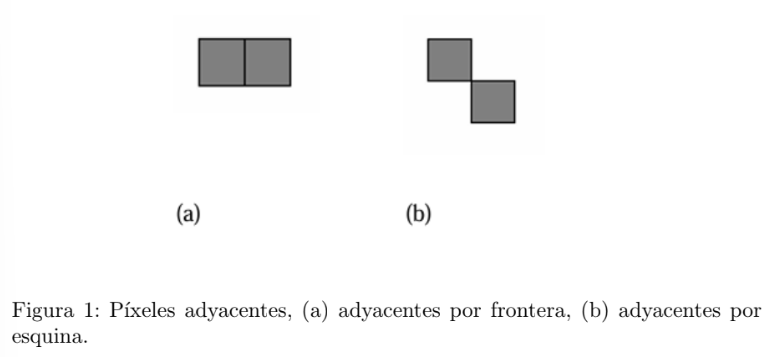


$$V_p =\left\lbrace p:p\in M_{\textrm{KL}} \right\rbrace ;M_{\textrm{KL}} \subset i_{\textrm{MN}} ;K=L=3,5,9$$


Para ilustrar las definiciones anteriores, se puede observar en la figura 2, vecindades de 4 y de vecindades 8, la primera formada por pixeles que son vecinos directos, mientras que la vecindad de 8 está formada tanto por vecinos directos como indirectos.

En el desarrollo de las técnicas de procesamiento de imágenes que involucren el análisis de una determinada región de la escena digital, es posible encontrar vecindades de 5x5 y hasta 9x9; básicamente la definición de las dimensiones de la matriz vecindad depende de la técnica que se esté desarrollando.

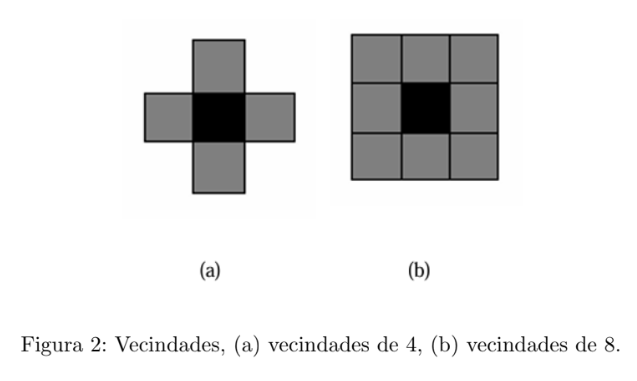

## Desarrollo

**Ejercicio: **Extracción de características con LBP para clasificación de texturas.

1. Descarga y organiza el conjunto de imágenes: Puedes utilizar el dataset clásico en análisis de texturas **Brodatz Texture Dataset**, el conjunto **Flickr Material Database (FMD)** o un conjunto personalizado con distintas clases: 

- corteza, ladrillo, burbujas, hierba, cuero, piel, rafia, arena, paja, agua, tejido, madera, lana.

2. Carga las imágenes y conviértelas a escala de grises: El **Brodatz Texture Dataset **original no incluye las etiquetas categóricas. Sin embargo, existen versiones modificadas y extensiones del dataset que sí incluyen etiquetas o puedes asignar etiquetas basadas en la tabla de referencia.

3. Implementación de LBP. El algoritmo de LBP sigue estos pasos:

- Para cada pixel central, comparar su intensidad con 8 vecinos.

- Generar un patrón binario (1 si el vecino $\ge$ central, 0 en otro caso).

- Convertir el binario a decimal y reemplazar el pixel central.

4. Extracción de características: Convertir cada imagen LBP en un histograma de 256 bins (para valores 0-255).

- Mostrar el histograma de una imagen individual.

- Comparar histogramas por clase (ej, madera vs. tela vs. piedra).

5. Clasificación y evaluación

- Divide los datos en entrenamiento (70%) y prueba (30%).

- Usa un modelo simple como vecinos más cercanos (k-NN) o Máquina de Soporte Vectorial (SVM) sobre los vectores de características y entrena el modelo.

- Calcula la exactitud en el conjunto de prueba.

- Visualiza las imágenes LBP para entender qué patrones se están detectando.

6. Visualización de resultados

- Descripción de los pasos realizados

- Resultados obtenidos (gráficas y análisis)

## Código

clc; clear; close all;
format short;

**Cargar Dataset**

imds = imageDatastore('KTH_TIPS',...
    'IncludeSubfolders', true,...
    'LabelSource', 'foldernames');

**Convertir a escala de grises y redimensionar**

imds.ReadFcn = @(loc)imresize(rgb2gray(imread(loc)), [200 200]);

**Extracción de características (LBP)**

numImages = numel(imds.Files);

radius = 2;          % Radio del vecindario
numNeighbors = 8;    % Número de puntos de muestreo
% numBins = 128; 

function lbp_image = computeLBP(image)
    [rows, cols] = size(image);
    lbp_image = zeros(rows-2, cols-2, 'uint8');
    
    for i = 2:rows-1
        for j = 2:cols-1
            center = image(i, j);
            % Comparar con los 8 vecinos (en orden clockwise)
            neighbors = [image(i-1, j-1), image(i-1, j), image(i-1, j+1), ...
                         image(i, j+1),   image(i+1, j+1), image(i+1, j), ...
                         image(i+1, j-1), image(i, j-1)];
            
            binary_pattern = (neighbors >= center);
            lbp_value = sum(binary_pattern .* 2.^(0:7)); % Convertir binario a decimal
            lbp_image(i-1, j-1) = lbp_value;
        end
    end
end

function features = extractLBPFeatures(images)
    num_images = numel(images.Files);
    features = zeros(num_images, 256); % 256 bins
    for k = 1:num_images
        lbp = computeLBP(readimage(images, k));
        hist = imhist(lbp, 256)';
        features(k, :) = hist / sum(hist); % Normalizar
    end

end

features = extractLBPFeatures(imds); % Matriz de características

**Preparar datos para clasificación**

labels = imds.Labels;
data = array2table(features);
data.Label = labels;

**Mostrar el histograma de una imagen individual**

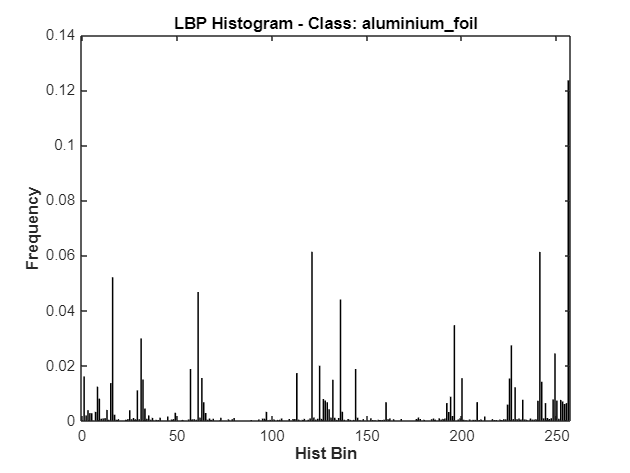

histograma = table2array(data(1, 1:256));
figure;
bar(histograma, 'k');
xlabel('Hist Bin', 'FontWeight', 'bold');
ylabel('Frequency', 'FontWeight', 'bold');
title(['LBP Histogram - Class: ', char(labels(1))], 'Interpreter', 'none');

**Comparación de los histogramas por clase**

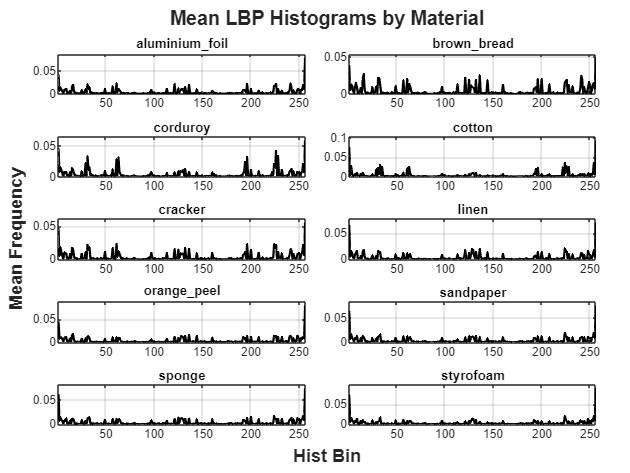

clases = categories(labels);
numClases = numel(clases);

figure;
t = tiledlayout(5, 2, 'Padding', 'compact', 'TileSpacing', 'compact');

for i = 1:numClases
    clase_actual = clases{i};
    
    idx = labels == clase_actual;
    
    % Extraer histogramas y promediar
    histogramas_clase = table2array(data(idx, 1:256));
    promedio_histograma = mean(histogramas_clase, 1);
    
    nexttile;
    plot(promedio_histograma, 'k', 'LineWidth', 1.5);
    title(strrep(clase_actual, '_', '\_'), 'Interpreter', 'tex');
    xlim([1, 256]);
    ylim([0, max(promedio_histograma)*1.1]);
    grid on;
end

% Etiquetas globales para los ejes
xlabel(t, 'Hist Bin', 'FontWeight', 'bold');
ylabel(t, 'Mean Frequency', 'FontWeight', 'bold');
sgtitle(t, 'Mean LBP Histograms by Material', 'FontWeight', 'bold');

**Dividir en conjunto de entrenamiento y prueba (70% - 30%)**

X = table2array(data(:, 1:256));
Y = labels;

Y_num = grp2idx(Y);

% Dividir en entrenamiento (70%) y prueba (30%)
rng('default');  % Para reproducibilidad
cv = cvpartition(Y_num, 'HoldOut', 0.3);

% Crear conjuntos
XTrain = X(cv.training, :);
YTrain = Y_num(cv.training);

XTest = X(cv.test, :);
YTest = Y_num(cv.test);

**K-NN**

knnModel = fitcknn(XTrain, YTrain,...
    'NumNeighbors', 3,...
    'Distance', 'euclidean',...
    'Standardize', true);

knnPred = predict(knnModel, XTest);
accuracyKNN = sum(knnPred == YTest)/numel(YTest);

**SVM**

template = templateSVM(...
    'Standardize', true,...
    'KernelFunction', 'linear',...
    'BoxConstraint', 1);

svmModel = fitcecoc(XTrain, YTrain,...
    'Learners', template,...
    'Coding', 'onevsall');

svmPred = predict(svmModel, XTest);
accuracySVM = sum(svmPred == YTest)/numel(YTest);

**Resultados**

fprintf('Exactitud KNN: %.2f%%\n', accuracyKNN*100);

Exactitud KNN: 92.18%


fprintf('Exactitud SVM: %.2f%%\n', accuracySVM*100);

Exactitud SVM: 93.83%


**Matriz de confusión**

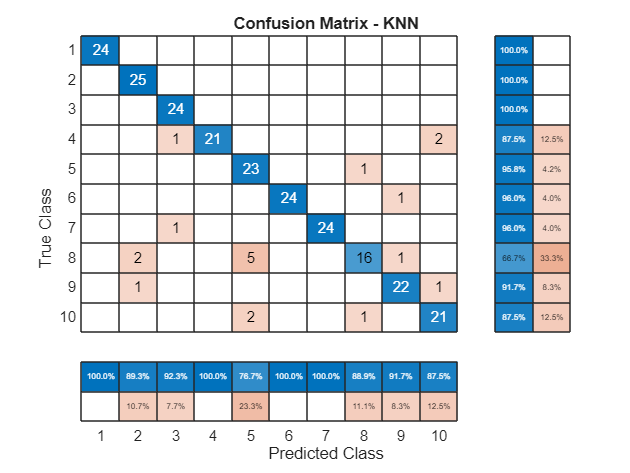

figure
confusionchart(YTest, knnPred,...
    'RowSummary', 'row-normalized',...
    'ColumnSummary', 'column-normalized',...
    'Title', 'Confusion Matrix - KNN');

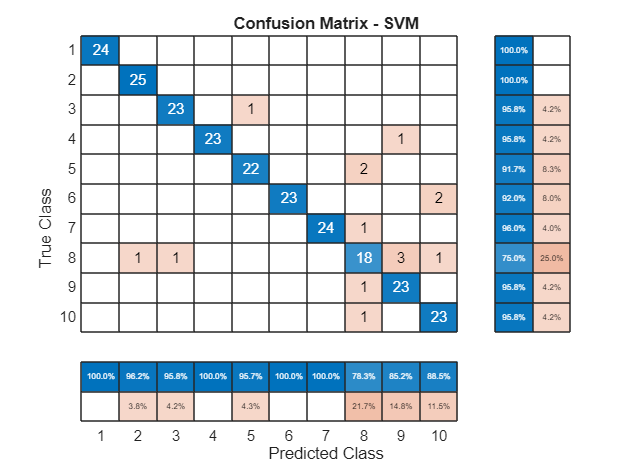

figure
confusionchart(YTest, svmPred,...
    'RowSummary', 'row-normalized',...
    'ColumnSummary', 'column-normalized',...
    'Title', 'Confusion Matrix - SVM');

Notamos que, en general, ambos modelos clasificaron bastante bien las clases *aluminium_foil*, *brown_bread *y *corduroy*. Por otra parte, la clase que menos veces fue clasificada correctamente fue la de *sandpaper.* El modelo de K-NN lo clasificó erróneamente como *cracker* en 5 ocasiones de 24. Por otro lado, el modelo de SVM la clasificó incorrectamente más veces como *corduroy*, pero en menor proporción (3 de 24). Analicemos los histogramas promedio individuales de estas tres clases:

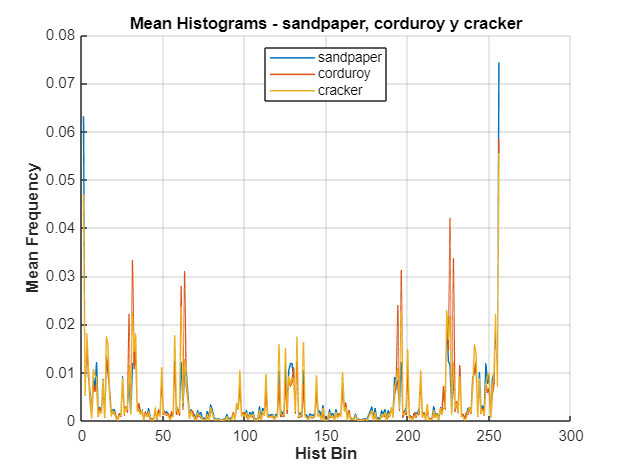

clasesSeleccionadas = {'sandpaper', 'corduroy', 'cracker'};

figure;
hold on;

colores = lines(length(clasesSeleccionadas));

for i = 1:length(clasesSeleccionadas)
    clase = clasesSeleccionadas{i};    
    indices = labels == clase;
    histogramasClase = data{indices, 1:256};
    histoPromedio = mean(histogramasClase, 1);
    plot(histoPromedio, 'LineWidth', 1, 'DisplayName', clase, 'Color', colores(i, :));
end

title('Mean Histograms - sandpaper, corduroy y cracker');
xlabel('Hist Bin', 'FontWeight', 'bold');
ylabel('Mean Frequency', 'FontWeight', 'bold');
legend('Location', 'best');
grid on;
hold off;

Como podemos ver, los histogramas de estas clases no difieren mucho entre sí, lo cual puede explicar razonablemente la confusión del modelo.

En cuanto a la comparación de los modelos, SVM supera a K-NN, lo que puede significar que las clases están separadas de forma más o menos lineal en el espacio de características.

## Conclusiones

En esta práctica se logró implementar exitosamente el descriptor Patrones Binarios Locales (LBP) en MATLAB como técnica para la extracción de características de texturas en imágenes. Se desarrolló un flujo completo que incluyó el cálculo del mapa LBP, la construcción de histogramas como vectores de características, así como la posterior clasificación utilizando el algoritmo k-NN (k-Nearest Neighbors) y la Máquina de Soporte Vectorial (SVM).

Durante la experimentación se aplicó la técnica sobre un conjunto de imágenes de materiales diversos, obteniendo un conjunto de características robustas para la representación de texturas. Estas características fueron luego utilizadas para entrenar y evaluar un clasificador k-NN, y un clasificador SVM, alcanzando una exactitud global superior al 90%, lo cual refleja una buena capacidad discriminativa del descriptor LBP.

La matriz de confusión evidenció que algunas clases como *aluminium_foil*, *brown_bread* o *corduroy* fueron clasificadas con alta precisión, mientras que otras como *sandpaper *y *cracker *presentaron mayor ambigüedad, probablemente debido a similitudes de sus texturas. Esto sugiere que LBP es una herramienta efectiva, pero puede beneficiarse de complementarse con otros descriptores si se busca mejorar la discriminación en casos complejos.

En resumen, se cumplió con el objetivo de la práctica al aplicar un enfoque completo de análisis de texturas mediante LBP y su integración con modelos de clasificación, lo que permite establecer una base sólida para tareas de reconocimiento visual automatizado basadas en textura.

## Referencias

- González, R., Woods, R., *Digital Image Processing*, Prentice Hall, 2008.

- Pratt, W. K., *Digital Image Processing*, John Wiley and Sons Inc, 2001.

- Jahne, B., *Digital Image Processing*, Springer, 2005.

- Sánchez Garreta, Josep Salvador; García, Vicente. *Special Issue on Data Preprocessing in Pattern Recognition: Recent Progress, Trends and Applications, 2002.* 